## EEL839 - Transmissão Digital

## Parte 2 - Treinamento da rede neural

Trabalho sobre o artigo: Adversarial training based channel estimation to mitigate jamming attacks in OFDM systems

Guilherme Araujo Thomaz

Este código implementa a parte do trabalho referente às simulações no Matlab para treinar a rede neural com os dados gerados pela parte 1.

## 1 - Leitura da base de dados e formatação

H = readmatrix('..\databases\train.csv');
x_train = H(:,1:2048);
y_train = H(:,2049:end);

H = readmatrix('..\databases\test.csv');
x_test = H(:,1:2048);
y_test = H(:,2049:end);

% Canais sem ruído
y_train_orig = readmatrix('..\databases\train_original.csv');
y_test_orig = readmatrix('..\databases\test_original.csv');

% histogram(abs(y_train(:))); Talvez depois valha a pena normalizar featureInputLayer

## 2 - Configuração da rede neural

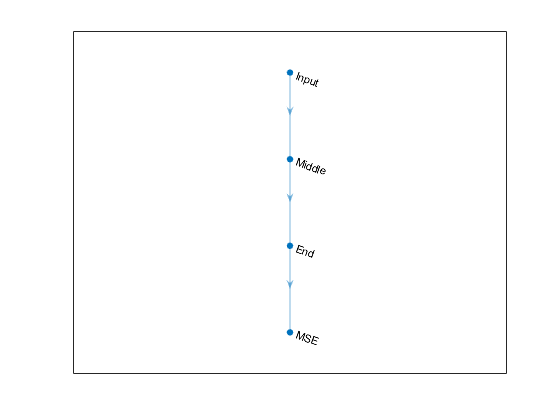

layers = [
    featureInputLayer(2048,"Normalization","none","Name","Input")
    fullyConnectedLayer(2048,"Name","Middle")
    fullyConnectedLayer(2048,"Name","End")
    regressionLayer("Name","MSE")
    ]; % Não coloquei não linearidades (sem função de ativação)

mini_batch_size  = 50;
max_epochs = 200; % Depois colocar 200
mi = 0.001;
validation_frequency = floor(numel(y_train)/mini_batch_size);

options = trainingOptions('adam', ...
    'MiniBatchSize',mini_batch_size, ...
    'MaxEpochs',max_epochs, ...
    'InitialLearnRate',mi, ... 
    'LearnRateSchedule','piecewise', ...  % tentar piecewise  
    'Shuffle','every-epoch', ...
    'ValidationData',{x_test,y_test}, ...
    'ValidationFrequency',validation_frequency, ...
    'Plots','training-progress', ... % depois, colocar none
    'Verbose',false);

% Tentar depois:
    %'LearnRateDropFactor',0.1, ...
    %'LearnRateDropPeriod',20, ...
lgraph = layerGraph(layers);
plot(lgraph);

## 3 - Treinamento da rede neural

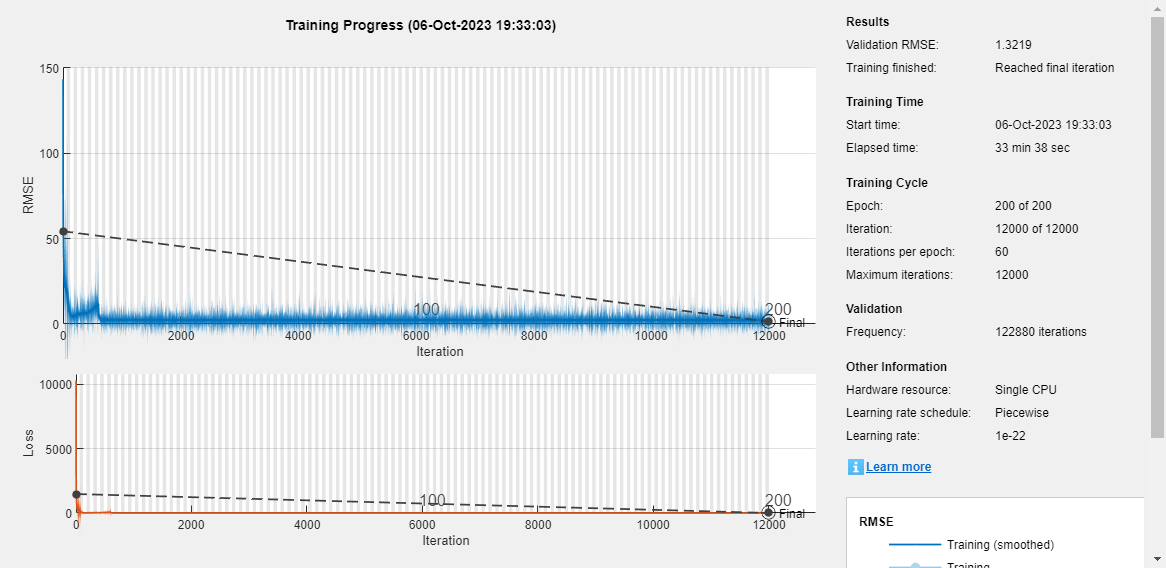

net = trainNetwork(x_train,y_train,layers,options);

net.Layers

ans =   4×1 Layer array with layers:

     1   'Input'    Feature Input       2048 features
     2   'Middle'   Fully Connected     2048 fully connected layer
     3   'End'      Fully Connected     2048 fully connected layer
     4   'MSE'      Regression Output   mean-squared-error with response 'Response'

## 4 - Inferência e teste

% Teste com conjunto de treino
y_predict_train = predict(net,x_train);
mse = immse(double(y_predict_train),y_train);
mse

mse = 0.0024

% Teste com conjunto de teste
y_predict_test = predict(net,x_test);
mse = immse(double(y_predict_test),y_test);
mse

mse = 8.5323e-04

% Desempenho em relação ao canal de verdade
y_predict_test = predict(net,x_test);
mse = immse(double(y_predict_test),y_test_orig);
mse

mse = 0.0025

## 5 - Ataque aleatório

H = readmatrix('..\databases\test_random_jamming.csv');
x_test_attack = H(:,1:2048);

% Canais sem ruído
y_test_attack_orig = readmatrix('..\databases\test_random_jamming_original.csv');

y_predict_test_attack = predict(net,x_test_attack);
mse = immse(double(y_predict_test_attack),y_test_attack_orig);
mse

mse = 0.0653